# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

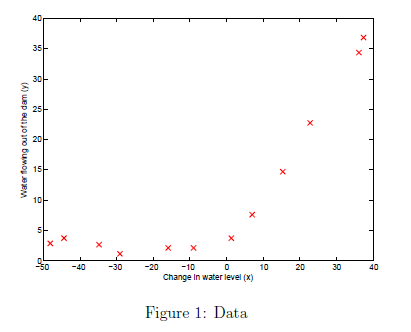

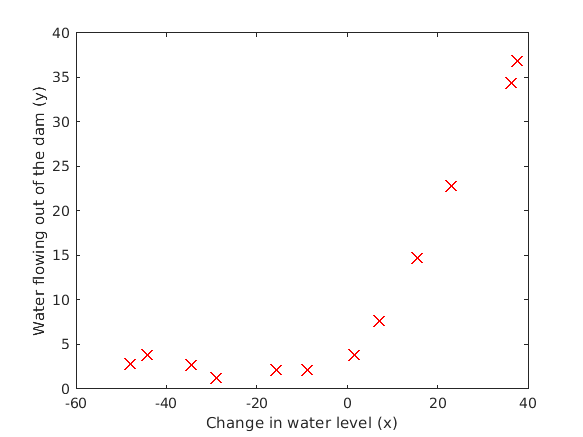

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment

load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

J = 303.9932

ylabel('Water flowing out of the dam (y)');

Cost at theta = [1 ; 1]: 303.993192

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

J = 303.9932

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j=0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

J = 140.9541

J = 139.9611

J = 138.0172

J = 132.5213

J = 119.0579

J = 105.2435

Iteration     1 | Cost: 1.052435e+02


J = 87.3070

J = 57.9883

J = 22.3739

Iteration     2 | Cost: 2.237391e+01


J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

Iteration     3 | Cost: 2.237391e+01


J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

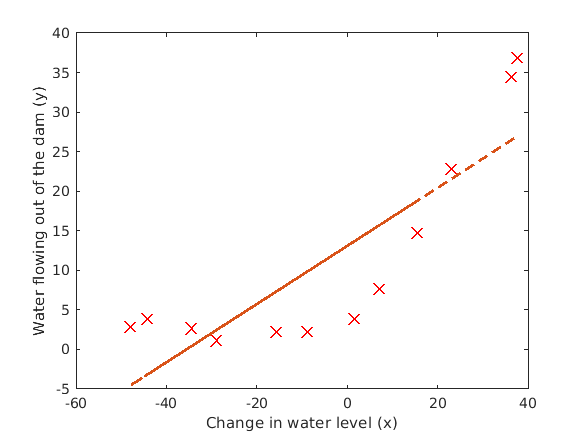

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

J = 2.2776

J = 1.8053

J = 1.0251

J = 3.6283e-04

Iteration     1 | Cost: 3.628289e-04


J = 2.1995e-05

Iteration     2 | Cost: 2.199486e-05


J = 0.0084

J = 2.4516e-05

J = 4.1575e-09

Iteration     3 | Cost: 4.157539e-09


J = 2.4891e-09

J = 4.2911e-10

Iteration     4 | Cost: 4.291129e-10


J = 1.3342e-08

J = 1.2217e-10

J = 1.2971e-11

Iteration     5 | Cost: 1.297070e-11


J = 2.3592e-09

J = 7.4403e-12

J = 1.0711e-13

Iteration     6 | Cost: 1.071136e-13


J = 1.2747e-09

J = 1.0730e-11

J = 5.1370e-14

J = 1.4182e-15

Iteration     7 | Cost: 1.418182e-15


J = 9.5394e-13

J = 4.0675e-15

J = 3.0966e-17

Iteration     8 | Cost: 3.096638e-17


J = 8.2338e-14

J = 5.6104e-16

J = 6.2364e-18

Iteration     9 | Cost: 6.236430e-18


J = 2.3924e-16

J = 1.9903e-18

J = 1.6436e-19

Iteration    10 | Cost: 1.643627e-19


J = 2.6089e-17

J = 9.0875e-20

J = 1.5157e-21

Iteration    11 | Cost: 1.515726e-21


J = 1.4269e-17

J = 1.1744e-19

J = 6.6241e-22

J = 2.4358e-23

Iteration    12 | Cost: 2.435846e-23


J = 1.5333e-20

J = 6.3058e-23

J = 4.2580e-25

Iteration    13 | Cost: 4.257960e-25


J = 1.7313e-21

J = 1.2770e-23

J = 1.1867e-25

J = 1.3209e-26

Iteration    14 | Cost: 1.320908e-26


J = 8.6353e-24

J = 3.6332e-26

J = 2.6663e-28

Iteration    15 | Cost: 2.666350e-28


J = 8.2073e-25

J = 5.7272e-27

J = 5.6798e-29

Iteration    16 | Cost: 5.679799e-29


J = 1.9883e-27

J = 1.6665e-29

J = 2.4652e-30

Iteration    17 | Cost: 2.465190e-30


J = 8.3461e-28

J = 3.5499e-30

J = 9.8608e-32

Iteration    18 | Cost: 9.860761e-32


J = 9.8608e-32

J = 0

Iteration    19 | Cost: 0.000000e+00


J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 0

J = 210.5224

J = 1.4830

J = 0.7204

J = 0.4282

Iteration     1 | Cost: 4.282328e-01


J = 0.4161

J = 0.3923

J = 0.3252

J = 0.1616

J = 8.2954e-30

Iteration     2 | Cost: 8.295365e-30


J = 4.0622e-18

J = 4.0621e-20

J = 4.0610e-22

J = 4.0504e-24

J = 3.9383e-26

J = 2.9584e-28

J = 4.9304e-32

Iteration     3 | Cost: 4.930381e-32


J = 1.4421e-30

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 4.9304e-32

J = 3.4719e-27

J = 3.7927e-29

J = 6.5328e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 1.1093e-31

J = 4.9304e-32

J = 110.3004

J = 197.7467

J = 196.7493

J = 194.7703

J = 188.9586

J = 172.6534

J = 133.9057

J = 102.1540

Iteration     1 | Cost: 1.021540e+02


J = 79.2852

J = 42.5587

J = 3.2866

Iteration     2 | Cost: 3.286595e+00


J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

Iteration     3 | Cost: 3.286595e+00


J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 3.2866

J = 45.0102

J = 317.9394

J = 316.9406

J = 314.9499

J = 309.0340

J = 291.7905

J = 244.5988

J = 143.8726

Iteration     1 | Cost: 1.438726e+02


J = 266.7254

J = 103.5224

Iteration     2 | Cost: 1.035224e+02


J = 75.3672

Iteration     3 | Cost: 7.536716e+01


J = 37.8849

J = 16.1542

Iteration     4 | Cost: 1.615422e+01


J = 177.4398

J = 3.6193

Iteration     5 | Cost: 3.619255e+00


J = 180.8799

J = 3.1356

J = 2.8468

Iteration     6 | Cost: 2.846783e+00


J = 60.0644

J = 3.3397

J = 2.8438

Iteration     7 | Cost: 2.843785e+00


J = 2.8916

J = 2.8435

Iteration     8 | Cost: 2.843471e+00


J = 2.8491

J = 2.8434

Iteration     9 | Cost: 2.843448e+00


J = 2.8436

J = 2.8434

Iteration    10 | Cost: 2.843439e+00


J = 2.8434

J = 2.8434

J = 2.8433

J = 2.8430

J = 2.8427

Iteration    11 | Cost: 2.842680e+00


J = 4.5466

J = 2.8597

J = 2.8429

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    12 | Cost: 2.842680e+00


J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    13 | Cost: 2.842679e+00


J = 2.8427

Iteration    14 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

Iteration    15 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

Iteration    16 | Cost: 2.842678e+00


J = 2.8435

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    17 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

Iteration    18 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    19 | Cost: 2.842678e+00


J = 2.8428

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    20 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    21 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

Iteration    22 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

Iteration    23 | Cost: 2.842678e+00


J = 2.8427

Iteration    24 | Cost: 2.842678e+00


J = 2.8427

Iteration    25 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

Iteration    26 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

Iteration    27 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

Iteration    28 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

Iteration    29 | Cost: 2.842678e+00


J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 2.8427

J = 48.3689

J = 255.1405

J = 254.1432

J = 252.1640

J = 246.3518

J = 230.0415

J = 191.2487

J = 159.2641

Iteration     1 | Cost: 1.592641e+02


J = 136.6149

J = 97.0355

J = 24.0497

Iteration     2 | Cost: 2.404966e+01


J = 2.2005e+04

J = 224.7448

J = 24.1448

J = 23.5414

Iteration     3 | Cost: 2.354137e+01


J = 22.8116

Iteration     4 | Cost: 2.281160e+01


J = 27.7690

J = 22.7697

Iteration     5 | Cost: 2.276969e+01


J = 22.6728

J = 22.5076

J = 22.2406

Iteration     6 | Cost: 2.224060e+01


J = 21.3947

J = 20.1165

J = 19.2061

Iteration     7 | Cost: 1.920606e+01


J = 14.7529

Iteration     8 | Cost: 1.475292e+01


J = 29.2721

J = 14.3057

Iteration     9 | Cost: 1.430565e+01


J = 13.8888

Iteration    10 | Cost: 1.388881e+01


J = 13.2733

Iteration    11 | Cost: 1.327330e+01


J = 17.5124

J = 13.2352

Iteration    12 | Cost: 1.323519e+01


J = 13.1941

Iteration    13 | Cost: 1.319411e+01


J = 13.2019

J = 13.1735

Iteration    14 | Cost: 1.317355e+01


J = 13.1541

Iteration    15 | Cost: 1.315411e+01


J = 13.8036

J = 13.1595

J = 13.1540

Iteration    16 | Cost: 1.315405e+01


J = 13.1562

J = 13.1541

J = 13.1540

Iteration    17 | Cost: 1.315405e+01


J = 13.1540

Iteration    18 | Cost: 1.315405e+01


J = 13.1540

Iteration    19 | Cost: 1.315405e+01


J = 13.1540

J = 13.1540

J = 13.1540

Iteration    20 | Cost: 1.315405e+01


J = 13.1540

J = 13.1540

Iteration    21 | Cost: 1.315405e+01


J = 13.1540

J = 13.1540

Iteration    22 | Cost: 1.315405e+01


J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

Iteration    23 | Cost: 1.315405e+01


J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 13.1540

J = 35.8652

J = 212.9920

J = 211.9953

J = 210.0210

J = 204.2528

J = 188.3390

J = 153.1141

Iteration     1 | Cost: 1.531141e+02


J = 163.1407

J = 135.0947

Iteration     2 | Cost: 1.350947e+02


J = 113.7334

Iteration     3 | Cost: 1.137334e+02


J = 81.9641

J = 44.0420

Iteration     4 | Cost: 4.404199e+01


J = 137.9124

J = 29.5743

Iteration     5 | Cost: 2.957435e+01


J = 88.6323

J = 27.1956

Iteration     6 | Cost: 2.719561e+01


J = 23.1681

J = 19.4928

Iteration     7 | Cost: 1.949283e+01


J = 101.1476

J = 20.2451

J = 19.4939

J = 19.4913

Iteration     8 | Cost: 1.949128e+01


J = 19.4883

J = 19.4826

J = 19.4691

J = 19.4571

Iteration     9 | Cost: 1.945708e+01


J = 19.4513

J = 19.4447

Iteration    10 | Cost: 1.944472e+01


J = 595.0660

J = 25.1991

J = 19.5021

J = 19.4453

J = 19.4447

J = 19.4447

Iteration    11 | Cost: 1.944472e+01


J = 19.4447

J = 19.4447

J = 19.4447

J = 19.4447

Iteration    12 | Cost: 1.944471e+01


J = 19.4447

J = 19.4447

J = 19.4446

J = 19.4445

Iteration    13 | Cost: 1.944453e+01


J = 19.4443

J = 19.4443

Iteration    14 | Cost: 1.944425e+01


J = 19.4442

J = 19.4441

Iteration    15 | Cost: 1.944411e+01


J = 19.4440

Iteration    16 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

Iteration    17 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

Iteration    18 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

Iteration    19 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

Iteration    20 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

Iteration    21 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

Iteration    22 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

Iteration    23 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

Iteration    25 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

Iteration    26 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

Iteration    28 | Cost: 1.944396e+01


J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 19.4440

J = 33.8300

J = 198.0212

J = 197.0244

J = 195.0505

J = 189.2851

J = 173.3960

J = 138.3936

Iteration     1 | Cost: 1.383936e+02


J = 151.8444

J = 121.0275

Iteration     2 | Cost: 1.210275e+02


J = 101.3004

Iteration     3 | Cost: 1.013004e+02


J = 70.7320

J = 34.5773

Iteration     4 | Cost: 3.457729e+01


J = 348.5837

J = 28.0871

Iteration     5 | Cost: 2.808710e+01


J = 70.2251

J = 27.3229

Iteration     6 | Cost: 2.732288e+01


J = 25.8753

J = 23.4651

J = 20.1151

Iteration     7 | Cost: 2.011513e+01


J = 122.1490

J = 21.1218

J = 20.1238

J = 20.1151

Iteration     8 | Cost: 2.011508e+01


J = 20.1149

J = 20.1146

J = 20.1138

J = 20.1114

J = 20.1069

Iteration     9 | Cost: 2.010693e+01


J = 20.1653

J = 20.1064

Iteration    10 | Cost: 2.010640e+01


J = 20.1085

J = 20.1063

Iteration    11 | Cost: 2.010629e+01


J = 20.1061

J = 20.1056

J = 20.1047

J = 20.1038

Iteration    12 | Cost: 2.010382e+01


J = 20.1000

J = 20.0985

Iteration    13 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    14 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    15 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    17 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    19 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    21 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

Iteration    23 | Cost: 2.009852e+01


J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 20.0985

J = 31.9710

J = 173.6956

J = 172.7004

J = 170.7383

J = 165.0794

J = 150.1493

J = 123.7772

Iteration     1 | Cost: 1.237772e+02


J = 500.3608

J = 120.2532

Iteration     2 | Cost: 1.202532e+02


J = 134.3269

J = 119.5134

Iteration     3 | Cost: 1.195134e+02


J = 118.0529

J = 115.2452

J = 107.7290

J = 93.3423

Iteration     4 | Cost: 9.334231e+01


J = 62.2215

J = 48.1353

Iteration     5 | Cost: 4.813526e+01


J = 47.3978

J = 25.7723

Iteration     6 | Cost: 2.577232e+01


J = 40.2168

J = 18.5777

Iteration     7 | Cost: 1.857772e+01


J = 18.3999

J = 18.2019

Iteration     8 | Cost: 1.820185e+01


J = 30.2517

J = 18.2672

J = 18.1944

Iteration     9 | Cost: 1.819445e+01


J = 18.1929

J = 18.1903

Iteration    10 | Cost: 1.819031e+01


J = 18.1830

J = 18.1743

Iteration    11 | Cost: 1.817431e+01


J = 21.0564

J = 18.2009

J = 18.1744

J = 18.1743

Iteration    12 | Cost: 1.817426e+01


J = 18.1742

J = 18.1740

J = 18.1739

Iteration    13 | Cost: 1.817389e+01


J = 18.1733

J = 18.1729

Iteration    14 | Cost: 1.817286e+01


J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

Iteration    15 | Cost: 1.817286e+01


J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 18.1729

J = 30.8624

J = 155.1733

J = 154.1786

J = 152.2211

J = 146.6033

J = 132.0430

J = 108.9984

Iteration     1 | Cost: 1.089984e+02


J = 204.0379

J = 106.4701

Iteration     2 | Cost: 1.064701e+02


J = 107.8325

J = 105.4742

Iteration     3 | Cost: 1.054742e+02


J = 103.4945

J = 99.6068

J = 88.5183

J = 60.4229

J = 22.6679

Iteration     4 | Cost: 2.266786e+01


J = 1.1841e+05

J = 1.2065e+03

J = 34.5035

J = 22.7859

J = 22.6690

J = 22.6679

J = 22.6679

Iteration     5 | Cost: 2.266786e+01


J = 22.6679

J = 22.6679

J = 22.6679

J = 22.6679

J = 22.6678

J = 22.6678

J = 22.6677

J = 22.6676

Iteration     6 | Cost: 2.266758e+01


J = 22.6670

J = 22.6659

J = 22.6626

J = 22.6533

J = 22.6307

J = 22.6094

Iteration     7 | Cost: 2.260941e+01


J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

Iteration     8 | Cost: 2.260941e+01


J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

Iteration     9 | Cost: 2.260941e+01


J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 22.6094

J = 31.1360

J = 140.3522

J = 139.3607

J = 137.4286

J = 132.0390

J = 119.5323

J = 110.8611

Iteration     1 | Cost: 1.108611e+02


J = 94.9176

J = 67.8310

J = 24.9754

Iteration     2 | Cost: 2.497543e+01


J = 3.7897e+04

J = 399.9790

J = 28.3543

J = 24.9721

J = 24.9642

Iteration     3 | Cost: 2.496421e+01


J = 24.9484

Iteration     4 | Cost: 2.494837e+01


J = 24.9318

Iteration     5 | Cost: 2.493176e+01


J = 24.9143

J = 24.9065

Iteration     6 | Cost: 2.490648e+01


J = 24.8598

J = 24.7900

J = 24.7433

Iteration     7 | Cost: 2.474331e+01


J = 24.4349

J = 23.9260

J = 23.2616

Iteration     8 | Cost: 2.326158e+01


J = 29.6364

J = 23.3253

J = 23.2622

J = 23.2616

J = 23.2616

J = 23.2616

Iteration     9 | Cost: 2.326158e+01


J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

J = 23.2616

Iteration    10 | Cost: 2.326156e+01


J = 23.2616

J = 23.2616

Iteration    11 | Cost: 2.326156e+01


J = 23.2616

Iteration    12 | Cost: 2.326156e+01


J = 23.2616

J = 23.2615

Iteration    13 | Cost: 2.326155e+01


J = 23.2615

J = 23.2615

J = 23.2615

Iteration    14 | Cost: 2.326147e+01


J = 23.2618

J = 23.2615

Iteration    15 | Cost: 2.326146e+01


J = 23.2615

J = 23.2615

Iteration    16 | Cost: 2.326146e+01


J = 23.2615

J = 23.2615

J = 23.2615

Iteration    17 | Cost: 2.326146e+01


J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

Iteration    18 | Cost: 2.326146e+01


J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 23.2615

J = 28.9362

J = 130.2375

J = 129.2465

J = 127.3182

J = 121.9636

J = 109.7705

J = 102.3394

Iteration     1 | Cost: 1.023394e+02


J = 86.5526

J = 60.3268

J = 24.4304

Iteration     2 | Cost: 2.443039e+01


J = 2.9528e+03

J = 53.6394

J = 24.7150

J = 24.4325

J = 24.4303

Iteration     3 | Cost: 2.443033e+01


J = 24.4302

J = 24.4300

J = 24.4297

Iteration     4 | Cost: 2.442972e+01


J = 24.4287

J = 24.4267

J = 24.4212

J = 24.4104

Iteration     5 | Cost: 2.441042e+01


J = 24.3857

J = 24.3585

Iteration     6 | Cost: 2.435852e+01


J = 24.3174

Iteration     7 | Cost: 2.431735e+01


J = 41.5893

J = 24.4867

J = 24.3187

J = 24.3173

Iteration     8 | Cost: 2.431733e+01


J = 24.3173

J = 24.3173

Iteration     9 | Cost: 2.431727e+01


J = 24.3173

J = 24.3172

Iteration    10 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

Iteration    11 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

Iteration    12 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

Iteration    14 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

J = 24.3172

Iteration    15 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

Iteration    16 | Cost: 2.431725e+01


J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 24.3172

J = 29.5514

J = 140.9541

J = 139.9611

J = 138.0172

J = 132.5213

J = 119.0579

J = 105.2435

Iteration     1 | Cost: 1.052435e+02


J = 87.3070

J = 57.9883

J = 22.3739

Iteration     2 | Cost: 2.237391e+01


J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

Iteration     3 | Cost: 2.237391e+01


J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 22.3739

J = 29.4338

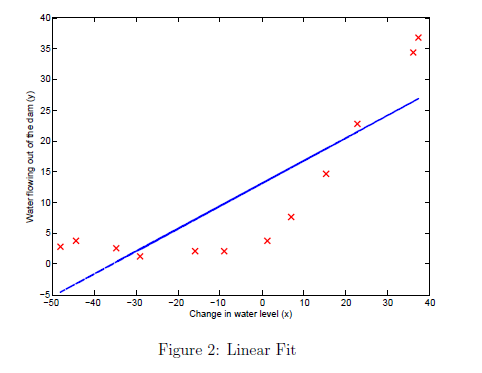

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

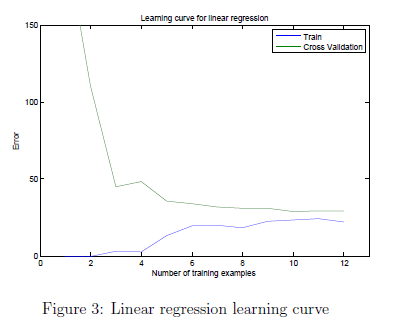

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

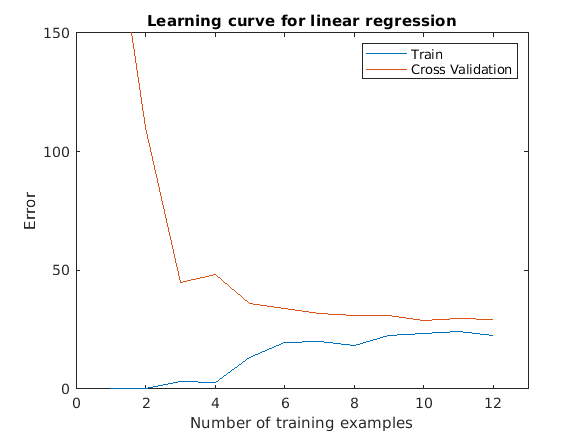

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')

xlabel('Number of training examples')
ylabel('Error')

# Training Examples	Train Error	Cross Validation Error


axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

  	1		0.000000	210.522449
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

J = 140.9541

J = 139.9602

J = 137.9930

J = 132.2563

J = 116.5321

J = 82.7308

Iteration     1 | Cost: 8.273077e+01


J = 26.8750

Iteration     2 | Cost: 2.687496e+01


J = 66.0868

J = 13.2778

Iteration     3 | Cost: 1.327780e+01


J = 3.4553

Iteration     4 | Cost: 3.455324e+00


J = 292.3912

J = 3.8972

J = 2.8705

Iteration     5 | Cost: 2.870493e+00


J = 2.4044

Iteration     6 | Cost: 2.404364e+00


J = 9.7729

J = 2.3728

Iteration     7 | Cost: 2.372779e+00


J = 2.2614

J = 2.0720

J = 1.7716

Iteration     8 | Cost: 1.771555e+00


J = 1.2103

Iteration     9 | Cost: 1.210317e+00


J = 1.1868

J = 0.9412

Iteration    10 | Cost: 9.411912e-01


J = 0.8038

Iteration    11 | Cost: 8.038237e-01


J = 2.1562

J = 0.7645

Iteration    12 | Cost: 7.644563e-01


J = 0.7031

J = 0.6753

Iteration    13 | Cost: 6.752853e-01


J = 0.5393

J = 0.4874

Iteration    14 | Cost: 4.874155e-01


J = 0.8655

J = 0.4406

Iteration    15 | Cost: 4.405967e-01


J = 1.4359

J = 0.4421

J = 0.4386

Iteration    16 | Cost: 4.385838e-01


J = 0.4350

J = 0.4309

Iteration    17 | Cost: 4.308533e-01


J = 0.4304

J = 0.4277

Iteration    18 | Cost: 4.277185e-01


J = 0.4226

J = 0.4193

Iteration    19 | Cost: 4.192792e-01


J = 0.4046

J = 0.3886

Iteration    20 | Cost: 3.886366e-01


J = 0.3772

J = 0.3723

Iteration    21 | Cost: 3.722755e-01


J = 0.3565

Iteration    22 | Cost: 3.565170e-01


J = 0.3608

J = 0.3493

Iteration    23 | Cost: 3.492964e-01


J = 0.3387

Iteration    24 | Cost: 3.386771e-01


J = 0.3886

J = 0.3379

Iteration    25 | Cost: 3.378672e-01


J = 0.3364

J = 0.3341

J = 0.3325

Iteration    26 | Cost: 3.325056e-01


J = 0.3292

Iteration    27 | Cost: 3.291998e-01


J = 0.3573

J = 0.3285

Iteration    28 | Cost: 3.284589e-01


J = 0.3272

J = 0.3259

Iteration    29 | Cost: 3.259218e-01


J = 0.3231

Iteration    30 | Cost: 3.230752e-01


J = 0.3220

J = 0.3216

Iteration    31 | Cost: 3.215988e-01


J = 0.3193

J = 0.3182

Iteration    32 | Cost: 3.181823e-01


J = 0.3133

Iteration    33 | Cost: 3.133315e-01


J = 0.3114

Iteration    34 | Cost: 3.113540e-01


J = 0.7398

J = 0.3150

J = 0.3113

Iteration    35 | Cost: 3.113292e-01


J = 0.3113

J = 0.3111

J = 0.3108

J = 0.3099

J = 0.3092

Iteration    36 | Cost: 3.092118e-01


J = 0.3061

Iteration    37 | Cost: 3.060503e-01


J = 0.3082

J = 0.3053

Iteration    38 | Cost: 3.053471e-01


J = 0.3041

J = 0.3030

Iteration    39 | Cost: 3.029894e-01


J = 0.3027

J = 0.3019

Iteration    40 | Cost: 3.018504e-01


J = 0.2999

J = 0.2980

Iteration    41 | Cost: 2.980391e-01


J = 0.3081

J = 0.2973

Iteration    42 | Cost: 2.973466e-01


J = 0.2961

J = 0.2941

J = 0.2924

Iteration    43 | Cost: 2.924419e-01


J = 0.2964

J = 0.2907

Iteration    44 | Cost: 2.906917e-01


J = 0.2875

J = 0.2832

Iteration    45 | Cost: 2.831528e-01


J = 0.3243

J = 0.2826

Iteration    46 | Cost: 2.826191e-01


J = 0.2816

J = 0.2800

J = 0.2785

Iteration    47 | Cost: 2.784828e-01


J = 0.2752

Iteration    48 | Cost: 2.751904e-01


J = 0.2761

J = 0.2733

Iteration    49 | Cost: 2.733255e-01


J = 0.2705

Iteration    50 | Cost: 2.705366e-01


J = 0.2677

J = 0.2665

Iteration    51 | Cost: 2.664947e-01


J = 0.2618

Iteration    52 | Cost: 2.618333e-01


J = 0.2638

J = 0.2602

Iteration    53 | Cost: 2.602037e-01


J = 0.2601

J = 0.2594

Iteration    54 | Cost: 2.593673e-01


J = 0.2585

Iteration    55 | Cost: 2.584804e-01


J = 0.2569

J = 0.2544

J = 0.2517

Iteration    56 | Cost: 2.516622e-01


J = 0.2640

J = 0.2499

Iteration    57 | Cost: 2.498747e-01


J = 0.2473

Iteration    58 | Cost: 2.472655e-01


J = 0.2444

J = 0.2425

Iteration    59 | Cost: 2.424906e-01


J = 0.2600

J = 0.2416

Iteration    60 | Cost: 2.416493e-01


J = 0.2411

Iteration    61 | Cost: 2.410610e-01


J = 0.2637

J = 0.2411

J = 0.2410

Iteration    62 | Cost: 2.410319e-01


J = 0.2410

J = 0.2409

J = 0.2409

Iteration    63 | Cost: 2.408572e-01


J = 0.2407

Iteration    64 | Cost: 2.406784e-01


J = 0.2403

J = 0.2397

J = 0.2385

Iteration    65 | Cost: 2.384866e-01


J = 0.2397

J = 0.2379

Iteration    66 | Cost: 2.379239e-01


J = 0.2373

Iteration    67 | Cost: 2.373126e-01


J = 0.2364

J = 0.2359

Iteration    68 | Cost: 2.359241e-01


J = 0.2383

J = 0.2356

Iteration    69 | Cost: 2.355521e-01


J = 0.2355

J = 0.2353

Iteration    70 | Cost: 2.353417e-01


J = 0.2350

Iteration    71 | Cost: 2.350283e-01


J = 0.2346

J = 0.2339

J = 0.2327

Iteration    72 | Cost: 2.326615e-01


J = 0.2362

J = 0.2322

Iteration    73 | Cost: 2.321719e-01


J = 0.2316

Iteration    74 | Cost: 2.316048e-01


J = 0.2316

J = 0.2314

Iteration    75 | Cost: 2.313558e-01


J = 0.2310

Iteration    76 | Cost: 2.310493e-01


J = 0.2312

J = 0.2309

Iteration    77 | Cost: 2.309459e-01


J = 0.2308

J = 0.2306

Iteration    78 | Cost: 2.306488e-01


J = 0.2303

Iteration    79 | Cost: 2.302907e-01


J = 0.2300

Iteration    80 | Cost: 2.299970e-01


J = 0.2298

Iteration    81 | Cost: 2.297859e-01


J = 0.2293

J = 0.2287

Iteration    82 | Cost: 2.287044e-01


J = 0.2290

J = 0.2283

Iteration    83 | Cost: 2.283285e-01


J = 0.2279

Iteration    84 | Cost: 2.278777e-01


J = 0.2294

J = 0.2278

Iteration    85 | Cost: 2.278155e-01


J = 0.2277

J = 0.2275

Iteration    86 | Cost: 2.275478e-01


J = 0.2277

J = 0.2275

Iteration    87 | Cost: 2.274783e-01


J = 0.2274

J = 0.2272

Iteration    88 | Cost: 2.272494e-01


J = 0.2273

J = 0.2272

Iteration    89 | Cost: 2.271506e-01


J = 0.2270

J = 0.2269

Iteration    90 | Cost: 2.268679e-01


J = 0.2271

J = 0.2268

Iteration    91 | Cost: 2.267699e-01


J = 0.2266

J = 0.2264

Iteration    92 | Cost: 2.263921e-01


J = 0.2276

J = 0.2263

Iteration    93 | Cost: 2.263441e-01


J = 0.2263

J = 0.2262

Iteration    94 | Cost: 2.262446e-01


J = 0.2261

Iteration    95 | Cost: 2.260972e-01


J = 0.2259

J = 0.2259

Iteration    96 | Cost: 2.258517e-01


J = 0.2256

Iteration    97 | Cost: 2.255816e-01


J = 0.2252

J = 0.2251

Iteration    98 | Cost: 2.250708e-01


J = 0.2242

J = 0.2233

Iteration    99 | Cost: 2.232534e-01


J = 0.2335

J = 0.2231

Iteration   100 | Cost: 2.230769e-01


J = 0.2228

J = 0.2223

J = 0.2220

Iteration   101 | Cost: 2.219797e-01


J = 0.2230

J = 0.2216

Iteration   102 | Cost: 2.216044e-01


J = 0.2211

Iteration   103 | Cost: 2.210548e-01


J = 0.2221

J = 0.2210

Iteration   104 | Cost: 2.209748e-01


J = 0.2208

J = 0.2206

J = 0.2202

Iteration   105 | Cost: 2.202154e-01


J = 0.2213

J = 0.2200

Iteration   106 | Cost: 2.200099e-01


J = 0.2198

Iteration   107 | Cost: 2.198124e-01


J = 0.2194

J = 0.2188

J = 0.2184

Iteration   108 | Cost: 2.184060e-01


J = 0.2623

J = 0.2186

J = 0.2184

Iteration   109 | Cost: 2.183636e-01


J = 0.2183

J = 0.2182

J = 0.2180

Iteration   110 | Cost: 2.180106e-01


J = 0.2181

J = 0.2178

Iteration   111 | Cost: 2.178441e-01


J = 0.2175

J = 0.2170

J = 0.2163

Iteration   112 | Cost: 2.163004e-01


J = 0.2138

J = 0.2115

Iteration   113 | Cost: 2.115433e-01


J = 0.2366

J = 0.2109

Iteration   114 | Cost: 2.109491e-01


J = 0.2108

J = 0.2106

Iteration   115 | Cost: 2.105937e-01


J = 0.2100

J = 0.2092

Iteration   116 | Cost: 2.091971e-01


J = 0.2084

Iteration   117 | Cost: 2.084205e-01


J = 0.2069

Iteration   118 | Cost: 2.069124e-01


J = 0.2050

J = 0.2027

Iteration   119 | Cost: 2.026549e-01


J = 0.2296

J = 0.2023

Iteration   120 | Cost: 2.023491e-01


J = 0.2020

Iteration   121 | Cost: 2.019891e-01


J = 0.2015

J = 0.2011

Iteration   122 | Cost: 2.011404e-01


J = 0.2002

Iteration   123 | Cost: 2.001783e-01


J = 0.1989

Iteration   124 | Cost: 1.989471e-01


J = 0.1983

Iteration   125 | Cost: 1.983415e-01


J = 0.2012

J = 0.1982

Iteration   126 | Cost: 1.981825e-01


J = 0.1979

J = 0.1978

Iteration   127 | Cost: 1.977855e-01


J = 0.1975

Iteration   128 | Cost: 1.974551e-01


J = 0.1972

Iteration   129 | Cost: 1.972294e-01


J = 0.1999

J = 0.1972

Iteration   130 | Cost: 1.971838e-01


J = 0.1971

J = 0.1970

Iteration   131 | Cost: 1.970388e-01


J = 0.1970

J = 0.1970

Iteration   132 | Cost: 1.969678e-01


J = 0.1970

J = 0.1969

Iteration   133 | Cost: 1.969347e-01


J = 0.1969

J = 0.1969

Iteration   134 | Cost: 1.969177e-01


J = 0.1969

J = 0.1969

Iteration   135 | Cost: 1.968533e-01


J = 0.1968

J = 0.1967

Iteration   136 | Cost: 1.967480e-01


J = 0.1966

J = 0.1963

Iteration   137 | Cost: 1.962848e-01


J = 0.1962

J = 0.1961

Iteration   138 | Cost: 1.960929e-01


J = 0.1958

J = 0.1955

Iteration   139 | Cost: 1.955391e-01


J = 0.1964

J = 0.1954

Iteration   140 | Cost: 1.953824e-01


    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

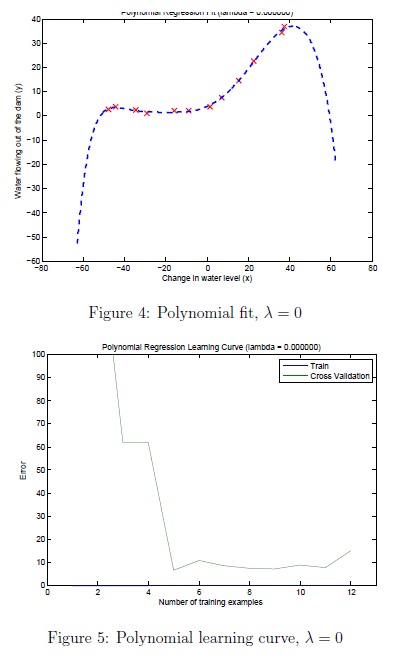

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

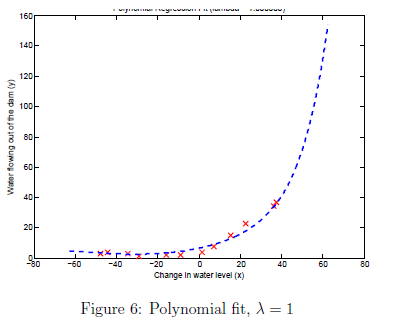

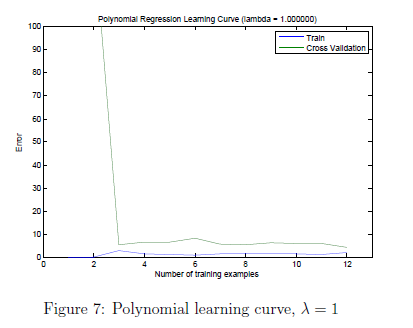

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

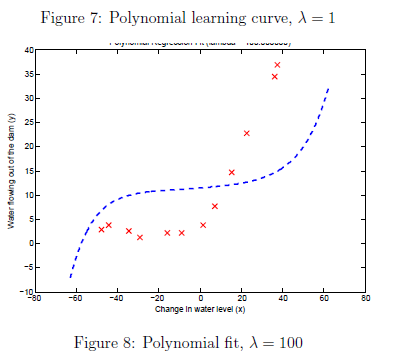

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

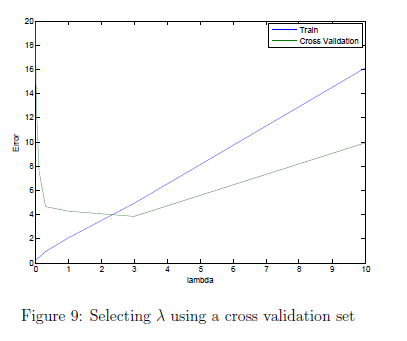

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

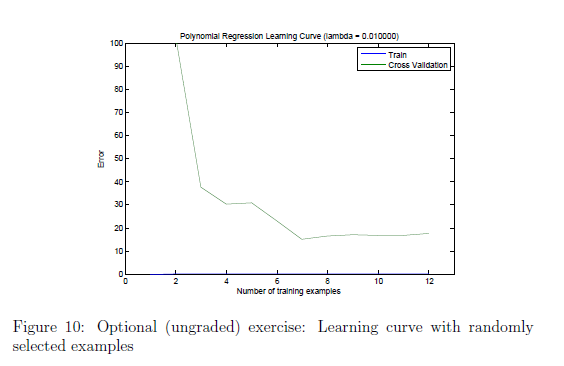

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

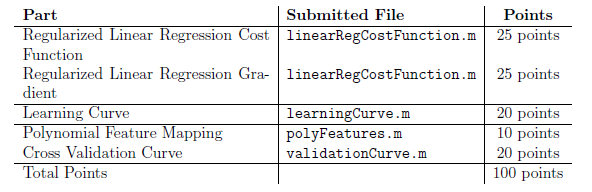

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.


.                        ex5_companion.mlx        fmincg.m                 linearRegCostFunction.m  submit.m                 validationCurve.m        
..                       ex5data1.mat             learningCurve.m          plotFit.m                token.mat                
ex5.mlx                  featureNormalize.m       lib                      polyFeatures.m           trainLinearReg.m         

